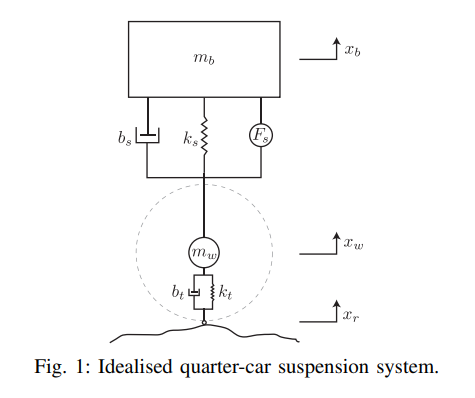

We use the above quater car mode with the following parameters


$$m_b =\;\textrm{kg};k_b =\;\frac{N}{m};$$

$$b_s =\;\frac{\textrm{Ns}}{s}$$



$$m_w =\;\mathrm{kg};k_t =\frac{N}{m};b_t =\frac{\mathrm{Ns}}{m}$$


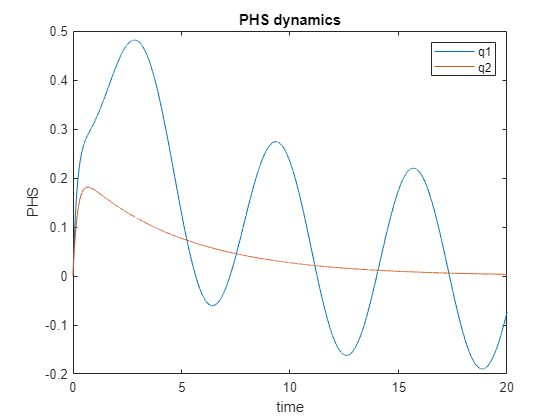

clc
clear
close all

tfinal = 20; dt = 0.001; % simulation parameters

% system parameters
mb=2.45; ks=950; bs=5;
mw=1; kt=2500; bt=5;
M = [mw+mb mb;mb mb]; K=[kt 0;0 ks];
G1 = [bt;0]; G2 = [-1;0]; 
D = diag([bt,bs]); G = [0;1];
A = [-D -eye(2);eye(2) zeros(2)];
B = [G;zeros(2,1)];

% desired control parameters
a1 = 3.45; a2=2.45; a3=2.45;
Md = [a1 a2;a2 a3];
b2=21;
Dd = [bt*a1/(mw+mb) 0;0 b2];
kz=294;
Kd = [kt*(mw+mb)/a1 0;0 kz];
Ja = [0 -1;1 0];

lambda = 0; % convergence rate for control law

% initial 
xr0 = 0; xr = xr0; xr_dot = 0; w=1;
xb0 = 0; vb0 = 1; xw0 = 0; vw0 = 1;
x0 = [xb0;vb0;xw0;vw0]; x = x0; t = 0;
p10 = mb*x(2); p1 = p10; p20 = mw*x(4); p2 = p20; p = [p1;p2];
q10 = x(1); q1 = q10; q20 = x(3); q2 = q20; q = [q1;q2];
phs0 = [p;q]; phs = phs0;
xw = q10 + xr0; xb = q20 + xw;
h=0; pe=0; ke=0; 

% initialize memory
PHS = []; T = []; 
Q = [];P = [];
Xb = []; Xw = []; Xr = []; Xr_dot = [];
H=[]; PE=[]; KE=[];

while (t <= tfinal)
    T = [T,t]; PHS = [PHS,phs];
    H=[H,h]; PE=[PE,pe]; KE=[KE,ke];
    Q = [Q,q]; P = [P,p]; 
    Xb = [Xb,xb]; Xw = [Xw,xw]; 
    Xr = [Xr,xr]; Xr_dot = [Xr_dot,xr_dot];

    %road profile
    xr = sin(w*t)+2; 
    xr_dot = w*cos(w*t);

    % system energy
    ke = 0.5*kt*q(1)^2+0.5*ks*q(2)^2;
    pe = 0.5*p'*inv(M)*p;
    h = ke + pe;
    
    % desired energy
    phi = 0.5*kz*q(2)^2; %desired potential energy shaping
    pe_des = 0.5*kt*q(1)^2*(mw+mb)/a1 + phi;
    H_des = 0.5*p'*inv(Md)*p + pe_des;
    
    % control law
    u = lambda*pinv(G)*(D*(inv(M)*p) + (Ja-Dd)*inv(Md)*p + K*q - Md*inv(M)*([kt*q(1)*((mw+mb)/a1);kz*q(2)]));
    %u = lambda*(h_hat)/2;

    phs = phs + dt*(A*phs + B*u + [G1;G2]*xr_dot);
    p = phs(1:2);
    q = phs(3:4);
    xw = q(1) + xr;
    xb = q(2) + xw;

    t = t + dt; % time increment
end

figure(1)
plot(T,Q);
ylabel('PHS')
xlabel('time')
legend('q1','q2')
title('PHS dynamics')

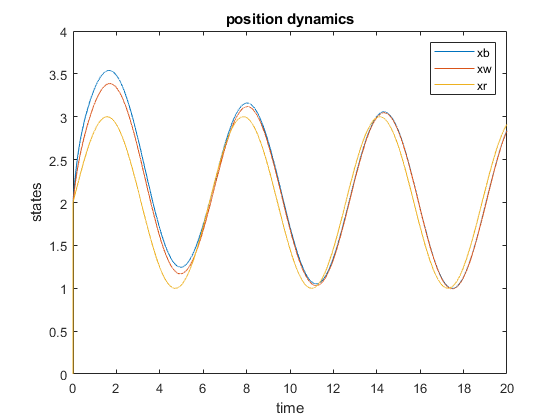

figure(2)
plot(T,Xb); hold on;
plot(T,Xw); hold on;
plot(T,Xr);
ylabel('states')
xlabel('time')
legend('xb','xw','xr')
title('position dynamics')
hold off

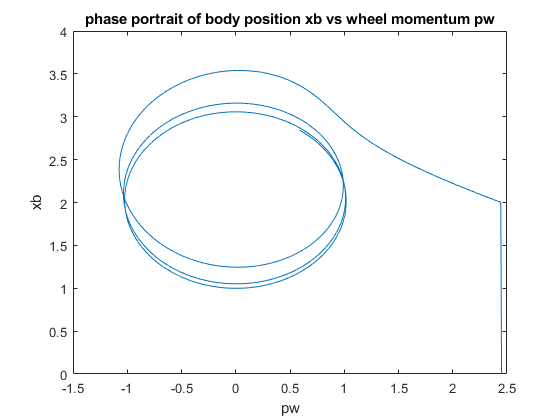

figure(3)
plot(P(1,:),Xb); hold on;
ylabel('xb')
xlabel('pw')
title('phase portrait of body position xb vs wheel momentum pw')
hold off

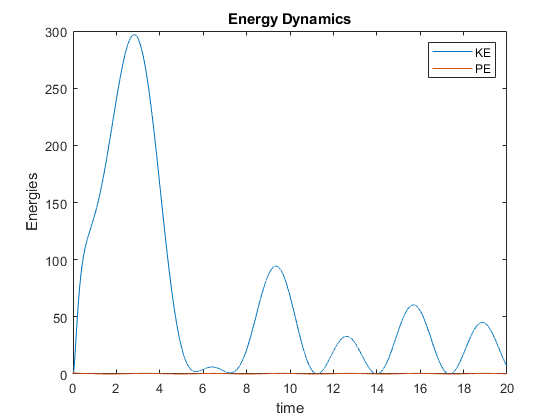

figure(4)
%plot(T,H_hat); hold on;
plot(T,KE); hold on;
plot(T,PE);
ylabel('Energies')
xlabel('time')
legend('KE','PE')
title('Energy Dynamics')
hold off